**Discussion HW 4**

Steven Henderson

**3 Introduction**

We are looking at the wheel with two masses, as shown in slide7 of the Discussion slides. Use the following parameters: the mass of the wheel is m`w` = 1.29 kg; R = 31 cm; M = 0.3 kg.

**4 Do This**

(A) Make a single plot of the normalized potential energy u = U/(M gR) as a function of θ for mass ratios μ = m/M = (0.7, 0.8, 1.1) and m`w` = 0. Make sure the three curves, one for each μ are clearly distinguishable and labeled.

Defining potential = 0 at the top of the wheel.


$$\begin{array}{l}
V_M =\mathrm{Mg}\left(R-\mathrm{Rcos}\phi \right)\\
V_m =\mathrm{mg}\left(-R-R\phi \right)\\
V=-\mathrm{MgR}\left(1+\cos \phi \right)-\mathrm{mgR}\left(1+\phi \right)\\
u=\frac{V}{\mathrm{MgR}}=-1-\cos \phi -\mu \left(1+\phi \right)
\end{array}$$


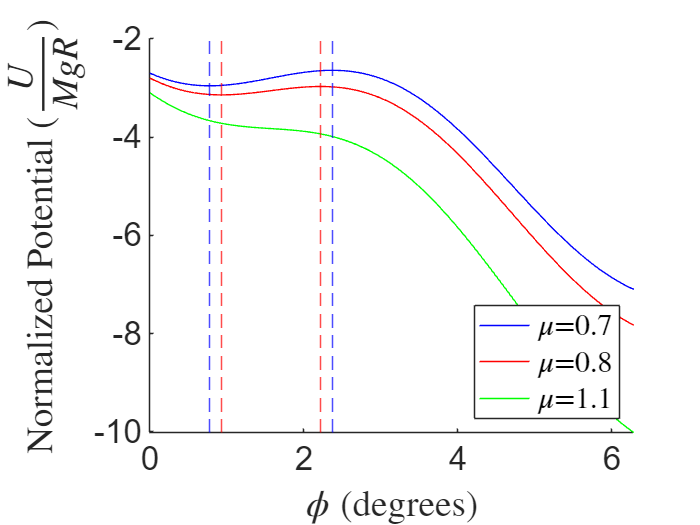

% Initial variables
mu = [0.7, 0.8, 1.1] ;
phispan = deg2rad(linspace(0, 360, 1000)) ;
% Find normalized potential energy
u_07 = - 1 - cos(phispan) - mu(1)*(1 + phispan) ;
u_08 = - 1 - cos(phispan) - mu(2)*(1 + phispan) ;
u_11 = - 1 - cos(phispan) - mu(3)*(1 + phispan) ;
% Plot normalized poetentials vs. phi
clf
hold on
plot(phispan, u_07, 'b')
plot(phispan, u_08, 'r')
plot(phispan, u_11, 'g')
hold off
% Plotting answers from part B to double check answers for B
xline(2.3648, 'b--')
xline(0.7736, 'b--')
xline(2.2139, 'r--')
xline(0.9246, 'r--')
legend('$\mu$=0.7', '$\mu$=0.8', '$\mu$=1.1', 'Interpreter', 'latex', 'Location', 'southeast')
ylabel('Normalized Potential ($\frac{U}{MgR}$)', 'Interpreter', 'latex')
xlabel('$\phi$ (degrees)', 'Interpreter', 'latex')
set(gca, 'Fontsize', 20)

(B) For each μ, find the angles of equilibrium with m`w` = 0, if any. Are they stable or unstable equilibria. Do these angles of equilibria change if you assume that the wheel has mass m`w` 6 = 0? If they do, give the new angles. Do these angles change as a function of the initial conditions, namely, the angle and angular speed at the moment of release (t = 0)

For Equilibirum potenial energy slope should equal 0 meaning no change in potential and therefore no change in position.


$$\begin{array}{l}
\frac{\mathrm{dV}}{d\phi }=\frac{d}{d\phi }\left(-\mathrm{MgR}\left(1+\cos \phi \right)-\mathrm{mgR}\left(1+\phi \right)\right)=\mathrm{MgRsin}\phi -\mathrm{mgR}\\
m=M\mu \\
\frac{\mathrm{du}}{d\phi }=\frac{d}{d\phi }\left(-1-\cos \phi -\mu \left(1+\phi \right)\right)=\sin \phi -\mu 
\end{array}$$


*From matlab code below:*

For all equilibria, the initial condition and the wheel mass should not matter as they are not in the derivative of the potential which is the method I am using to find the equilbria. This makes sense as finding the equilibria is a matter of forces in which the mass of the wheel is distributed equally and does not contribute as well as the initial conditions not chaning the forces on the masses (except for the masses themselves).

*Note: The way the potential was set up it is always negative, to find if a equilibria is stable or not you need to think of the graph upside down*

For mu = 0.7 it was found that the equalibria are at 0.77361 and 2.3648 radians. Looking at the potential graph from part A, the equilibria at 0.77 radians is unstable while the one at 2.3 radians is stable.

For mu = 0.8 it was found that the equalibria are at 0.92455 and 2.2139 radians. Just as for mu = 0.8, the equilibria at 0.92 radians is unstable while the equilibria at 2.2 radians is stable .

For mu = 1.1 it was found that there are no equilibria and the masses will spin out the wheel as m is larger than M.

% Function for getting dV/dphi for different mus and phispan
% returns array
function out = dVdphi(mu, phispan)
   % Initial variables
    M = 0.3 ;
    g = 10 ;
    R = 0.31 ; 
    % Function for dVdphi
    out = M*g*R*sin(phispan) - M*mu*g*R ;
end
func_07 = dVdphi(mu(1), phispan) ;
func_08 = dVdphi(mu(2), phispan) ;
func_11 = dVdphi(mu(3), phispan) ;

% Function to check where an array crosses the x-axis
function indicies = crossx(array)
    indicies = [] ;
    % Loop over elements to check where signs flip
    for i = 1:length(array) - 1
        if (array(i) >= 0 && array(i + 1) < 0) || (array(i) <= 0 && array(i + 1) > 0)
            indicies(end + 1) = i ;
        end
    end
end

% Function for getting values from an array with an array
function values = getVals(input_array, indicies)
    values = [] ;
    % Loop over indicies and add the values of the array at that index to
    % values
    for i = 1:length(indicies + 1)
        values(end + 1) = input_array(indicies(i)) ;
    end
end
% Get intercepts of each function of mu
intercepts_07 = getVals(phispan, crossx(func_07)) ;
intercepts_08 = getVals(phispan, crossx(func_08)) ;
intercepts_11 = getVals(phispan, crossx(func_11)) ;
% Display results
results_07 = ['Intercepts for mu = 0.7: ', num2str(intercepts_07)] ; 
results_08 = ['Intercepts for mu = 0.8: ', num2str(intercepts_08)] ;
results_11 = 'No intercepts for mu = 1.1' ;
disp(results_07)

Intercepts for mu = 0.7: 0.77361      2.3648


disp(results_08)

Intercepts for mu = 0.8: 0.92455      2.2139


disp(results_11)

No intercepts for mu = 1.1


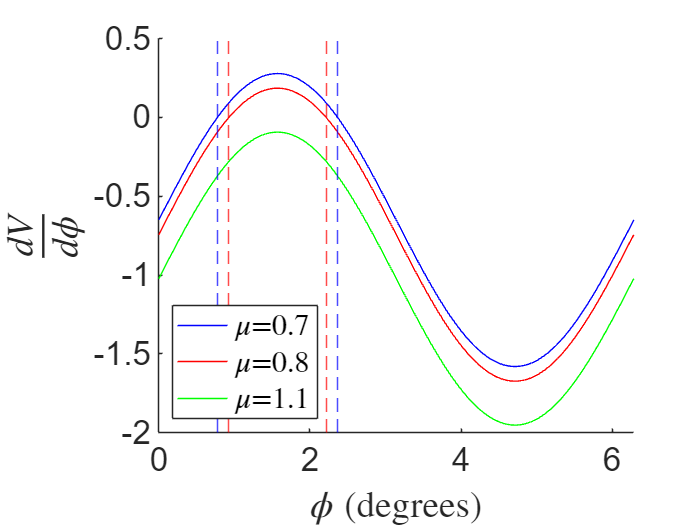

% Plot results
clf
hold on
plot(phispan, func_07, 'b') 
plot(phispan, func_08, 'r') 
plot(phispan, func_11, 'g') 
legend('$\mu$=0.7', '$\mu$=0.8', '$\mu$=1.1', 'Interpreter', 'latex', 'Location', 'southwest')
ylabel('$\frac{dV}{d\phi}$', 'Interpreter', 'latex')
xlabel('$\phi$ (degrees)', 'Interpreter', 'latex')
set(gca, 'Fontsize', 20)
% Plot intercepts
xline(2.3648, 'b--', 'HandleVisibility', 'off')
xline(0.7736, 'b--', 'HandleVisibility', 'off')
xline(2.2139, 'r--', 'HandleVisibility', 'off')
xline(0.9246, 'r--', 'HandleVisibility', 'off')

(C) Derive the equation of motion (for an arbitrary μ) with m`w` = 0.


$$K=\frac{1}{2}{\mathrm{mv}}^2 +\frac{1}{2}{\mathrm{Mv}}^2 =\frac{1}{2}\left(m+M\right){\left(R\overset{\ldotp }{\phi} \right)}^2$$



$$\begin{array}{l}
V=-\mathrm{MgR}\left(1+\cos \phi \right)-\mathrm{mgR}\left(1+\phi \right)\\
L=K-U=\frac{1}{2}\left(m+M\right){\left(R\overset{\ldotp }{\phi} \right)}^2 -\mathrm{MgR}\left(1+\cos \phi \right)-\mathrm{mgR}\left(1+\phi \right)\\
\frac{\partial L}{\partial \phi }=\mathrm{MgRsin}\phi -\mathrm{mgR}\\
\frac{\partial L}{\partial \overset{\ldotp }{\phi} }=\left(m+M\right)R^2 \overset{\ldotp }{\overset{\ldotp }{\phi} \to \frac{d}{\mathrm{dt}}} \left(\frac{\partial L}{\partial \overset{\ldotp }{\phi} }\right)=\left(m+M\right)R^2 \overset{\ldotp \ldotp }{\phi} \\
\left(m+M\right)R^2 \overset{\ldotp \ldotp }{\phi} =\mathrm{MgRsin}\phi -\mathrm{mgR}\\
\overset{\ldotp \ldotp }{\phi} =\frac{\mathrm{Mgsin}\phi }{R\left(m+M\right)}-\frac{\mathrm{mg}}{R\left(m+M\right)}
\end{array}$$


(D) Find the frequency of small oscillations when μ = 0.8 (still with m`w` = 0).


$$\begin{array}{l}
\phi =\phi_{\mathrm{eq}} +\zeta \left(t\right)\\
\overset{\ldotp \ldotp }{\phi} =\frac{\mathrm{Mgsin}\phi }{R\left(m+M\right)}-\frac{\mathrm{mg}}{R\left(m+M\right)}\to \overset{\ldotp \ldotp }{\zeta} =\frac{\mathrm{Mgsin}\left(\phi +\zeta \right)}{R\left(m+M\right)}-\frac{\mathrm{mg}}{R\left(m+M\right)}\\
\mathrm{Taylor}\;\mathrm{Expansion}\;\mathrm{of}\;\sin \phi \;\mathrm{around}\;\phi_{\mathrm{eq}} :\\
\sin \phi =\sin \phi_{\mathrm{eq}} +\zeta \cos \phi_{\mathrm{eq}} \\
m=M\mu \\
\overset{\ldotp \ldotp }{\zeta} =\frac{\mathrm{gsin}\phi_{\mathrm{eq}} +g\zeta \cos \phi_{\mathrm{eq}} }{R\left(\mu +1\right)}-\frac{\mu g}{R\left(\mu +1\right)}\\
\mathrm{For}\;\mathrm{small}\;\mathrm{oscillations},\mathrm{the}\;\mathrm{masses}\;\mathrm{have}\;\mathrm{to}\;\mathrm{be}\;\mathrm{in}\;\mathrm{stable}\;\mathrm{equilibria}\;\mathrm{or}\;\mathrm{else}\;\mathrm{they}\;\mathrm{will}\;\mathrm{not}\;\mathrm{return}\;\mathrm{to}\;\phi_{\mathrm{eq}} \\
\mathrm{So},\phi_{\mathrm{eq}} =2\ldotp 2139,\mathrm{from}\;\mathrm{part}\;B\\
\mathrm{Relating}\;\mathrm{this}\;\mathrm{equation}\;\mathrm{to}\;a\;\mathrm{harmonic}\;\mathrm{oscillator}\;\mathrm{where},\\
a=-\omega^2 x\\
\mathrm{Drop}\;\mathrm{constants}\;\mathrm{not}\;\mathrm{relating}\;\mathrm{to}\;\zeta \;\mathrm{and}\;\mathrm{we}\;\mathrm{get},\\
\overset{\ldotp \ldotp }{\zeta} =\frac{\zeta \mathrm{gcos}\phi_{\mathrm{eq}} }{R\left(\mu +1\right)}+C\\
\mathrm{where},\\
-\omega^2 =\frac{\mathrm{gcos}\phi_{\mathrm{eq}} }{R\left(\mu +1\right)}\\
\omega =\sqrt{-\frac{\mathrm{gcos}\phi_{\mathrm{eq}} }{R\left(\mu +1\right)}}=\sqrt{-\frac{\mathrm{gcos}\left(2\ldotp 2139\right)}{0\ldotp 31\left(0\ldotp 8+1\right)}}=3\ldotp 27\frac{\mathrm{rad}}{s}\\
T=\frac{2\pi }{\omega }=1\ldotp 91s\\
f=\frac{1}{T}=0\ldotp 52\mathrm{Hz}
\end{array}$$


(E) When you make observations you find that the frequency calculated in the previous section is not correct. Why? Fix the Lagrangian and the equation of motion and find a new frequency. 

There is no term for the wheel, the wheel would add rotational kinetic energy so,


$$\begin{array}{l}
K_{\mathrm{wheel}} =\frac{1}{2}I\omega^2 =\frac{1}{2}\left({m_w R}^2 \right){\overset{\ldotp }{\phi} }^2 \\
K=\frac{1}{2}\left(m+M\right){\left(R\overset{\ldotp }{\phi} \right)}^2 +\frac{1}{2}\left({m_w R}^2 \right){\overset{\ldotp }{\phi} }^2 \\
L=K-U=\frac{1}{2}\left(m+M\right){\left(R\overset{\ldotp }{\phi} \right)}^2 +\frac{1}{2}\left({m_w R}^2 \right){\overset{\ldotp }{\phi} }^2 -\mathrm{MgR}\left(1+\cos \phi \right)-\mathrm{mgR}\left(1+\phi \right)\\
\frac{\partial L}{\partial \phi }=\mathrm{MgRsin}\phi -\mathrm{mgR}\\
\frac{\partial L}{\partial \overset{\ldotp }{\phi} }=\left(m+M\right)R^2 \overset{}{\overset{\ldotp }{\phi} +m_w R^2 \overset{\ldotp }{\phi} \to \frac{d}{\mathrm{dt}}} \left(\frac{\partial L}{\partial \overset{\ldotp }{\phi} }\right)=\left(m+M\right)R^2 \overset{\ldotp \ldotp }{\phi} +{m_w } R^2 \overset{\ldotp \ldotp }{\phi} =\overset{\ldotp \ldotp }{\phi} R^2 \left(M+m+m_w \right)\\
\overset{\ldotp \ldotp }{\phi} R^2 \left(M+m+m_w \right)=\mathrm{MgRsin}\phi -\mathrm{mgR}\\
\overset{\ldotp \ldotp }{\phi} =\frac{\mathrm{Mgsin}\phi }{R\left(m+M+m_w \right)}-\frac{\mathrm{mg}}{R\left(m+M+m_w \right)}
\end{array}$$



$$\begin{array}{l}
\overset{\ldotp \ldotp }{\phi} =\frac{\mathrm{Mgsin}\phi }{R\left(m+M+m_w \right)}-\frac{\mathrm{mg}}{R\left(m+M+m_w \right)}\to \overset{\ldotp \ldotp }{\zeta} =\frac{\mathrm{Mgsin}\left(\phi_{\mathrm{eq}} +\zeta \right)}{R\left(m+m_w +M\right)}-\frac{\mathrm{mg}}{R\left(m+m_w +M\right)}\\
\overset{\ldotp \ldotp }{\zeta} =\frac{\mathrm{Mgsin}\left(\phi_{\mathrm{eq}} +\zeta \right)}{R\left(m+m_w +M\right)}+C=\frac{\mathrm{Mg}\left(\sin \phi_{\mathrm{eq}} +\zeta \cos \phi_{\mathrm{eq}} \right)}{R\left(m+m_w +M\right)}+C=\frac{\mathrm{Mgcos}\phi_{\mathrm{eq}} \zeta }{R\left(m+m_w +M\right)}+D\\
-\omega^2 =\frac{\mathrm{Mgcos}\phi_{\mathrm{eq}} }{R\left(\mu M+M+m_w \right)}\\
\omega =\sqrt{-\frac{\mathrm{Mgcos}\phi_{\mathrm{eq}} }{R\left(\mu M+M+m_w \right)}}=1\ldotp 78\;\frac{\mathrm{rad}}{s}\\
T=3\ldotp 5s\\
f=0\ldotp 28\;\mathrm{Hz}
\end{array}$$


(F) Optional (bonus 5 points) - the equation of motion can not be solved anlytically but it can be solved numerically. Write code to solve it exactly and give initial conditions such that the system executes small oscillations. Compare the exact numeric sollution to the pen-and-paper calculation.

These results are similar, form the code below, the period would  be 3.43s and the pen and paper solution found 3.5s. This means this is the correct equation of motion

% function for phi double dot
function phidot = odefun(t, phi)
    M = 0.3 ;
    g = 10 ;
    mw = 1.29 ;
    m = 0.8*M ;
    R = 0.31 ;
    % set values for phi dot and phi double dot
    phidot(1) = phi(2) ;
    phidot(2) = ((M*g*sin(phi(1))) / (R*(m+M+mw))) - ((m*g) / (R*(m+M+mw))) ;
    phidot = phidot' ;
end
iphi = [2.2139, 0] ;
tspan = linspace(0, 20, 100) ;
[t, phi] = ode45(@odefun, tspan, iphi) ;
% Find period of result
prev_value = phi(1) ;
prev_time = t(1) ;
period = 0 ;
% Loop through values of phi
for i = 2:length(phi) - 2
    threshold = 0.00001 ;
    % Check if value is within a certain threshold of similarity
    if (phi(i) < prev_value + threshold) && (phi(i) > prev_value - threshold)
        % set period to be time at same value - previous time of value
        period = t(i) - prev_time ;
        break;
    end
end
% Display results
disp(period)

    3.4343



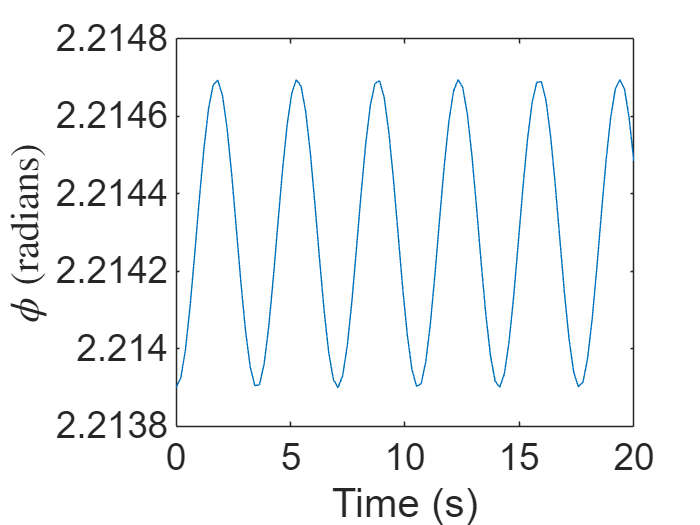

% Plot results
clf
plot(t, phi(:, 1))
xlabel('Time (s)')
ylabel('$\phi$ (radians)', 'Interpreter', 'latex')
xticks(linspace(0, 20, 5))
set(gca, 'fontsize', 22)